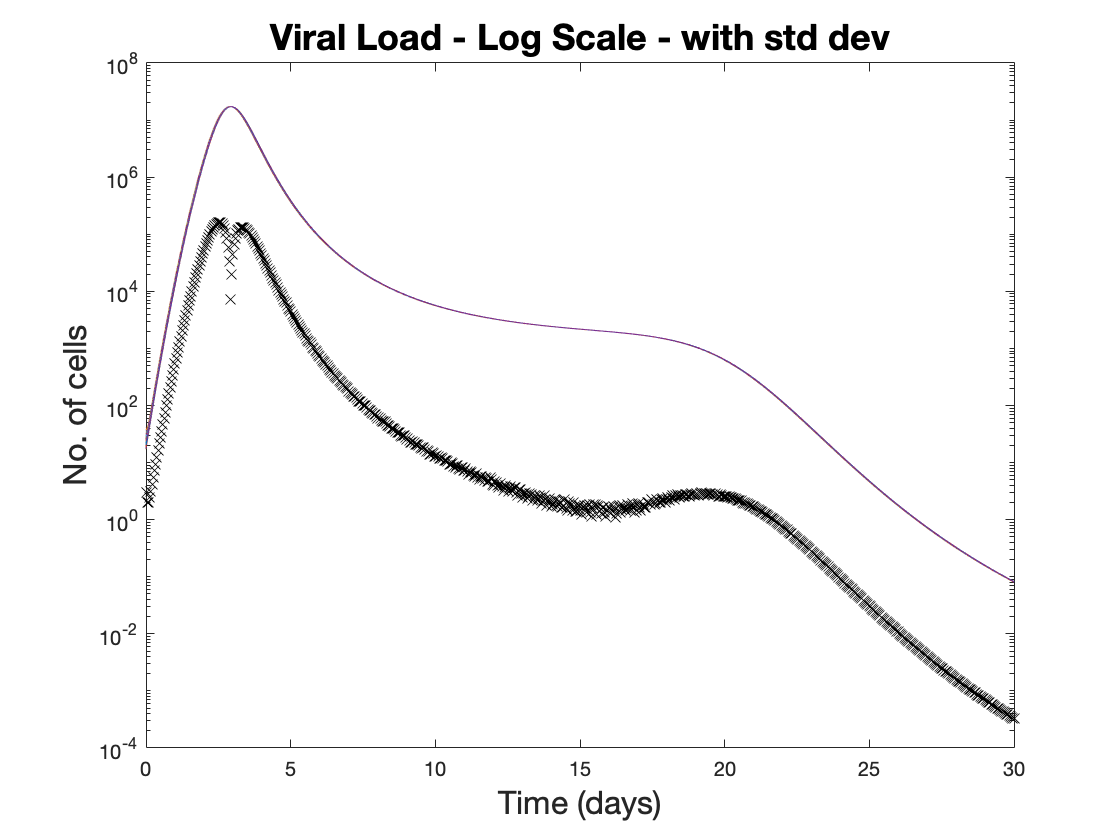

clear
close all
clc

beta = 10^(-7.23); k = 0.08; m = 3.21; r = 10; q = 0.000024;
delta = 3.13; parpi = 10^(2.59); deltaE = 1; c = 15; omeg = 10^(-4.55);
gamm = 15; phi = 100; 
dy = @(t,y) [-beta*y(1)*y(3); (beta*y(1)*y(3))-(delta*(y(2)^k)*y(2))-((m*y(2)*(y(6)^r))/((y(6)^r)+(phi^r))) ...
    ; (parpi*y(2))-(gamm*y(3)); (omeg*y(2)*y(4))-(q*y(4)); q*(y(4)-y(5)); (q*y(5))-(deltaE*y(6))]; 
tspan=linspace(0,30,720); %number of points we want
for i=1:100
    beta=10^normrnd(-7.23,0.2);
    k=normrnd(0.08,0.02);
    m=normrnd(3.21,0.33);
    delta=normrnd(3.13,0.02);
    parpi=10^normrnd(2.59,0.05);
    omeg=10^normrnd(-4.55,0.01);
    %rng('shuffle')
    ic = [10^7; 1; parpi/c; 1; 0; 0];
    [ta,ya] = ode45(dy,tspan,ic);
    yi(:,:,i)=interp1(tspan,ya,ta);
    
%     [t y] = diffn(ic);
%     ti(:,i) = t; yi(:,:,i) = y;
 
end
% y1=yi(:,1,:);
% y1=permute(y1,[1 3 2]);
% stdy1=std(y1')';
% plot(tspan,y1);
% hold on
% plot(tspan, stdy1, 'xk');
% hold off
% title('Susceptible Cells - Normal Scale - with std dev');
% y2=yi(:,2,:);
% y2=permute(y2,[1 3 2]);

y3=yi(:,3,:);
y3=permute(y3,[1 3 2]);
stdy3=std(y3')';
semilogy(tspan,y3); 
hold on
semilogy(tspan, stdy3, 'xk');
hold off
title('Viral Load - Log Scale - with std dev','FontSize',18);
xlabel('Time (days)','FontSize',16);
ylabel('No. of cells','FontSize',16);

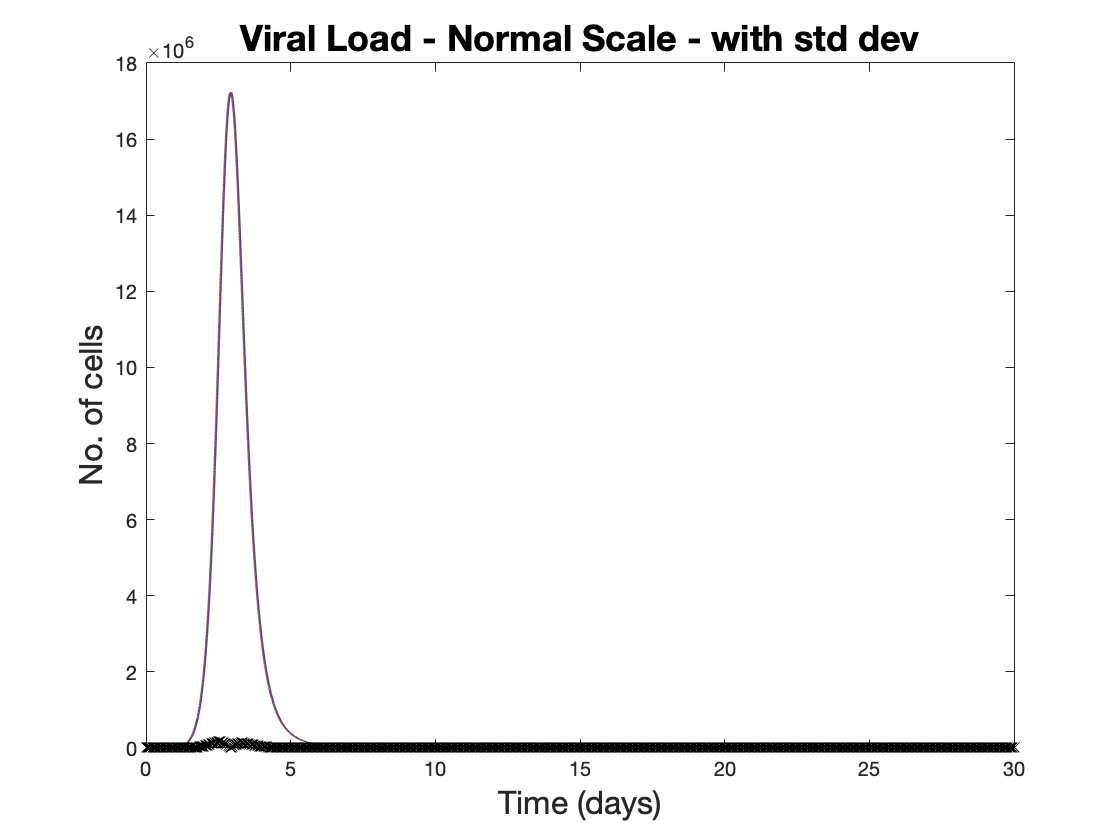


plot(tspan,y3); 
hold on
plot(tspan, stdy3, 'xk');
hold off
title('Viral Load - Normal Scale - with std dev','FontSize',18);
xlabel('Time (days)','FontSize',16);
ylabel('No. of cells','FontSize',16);

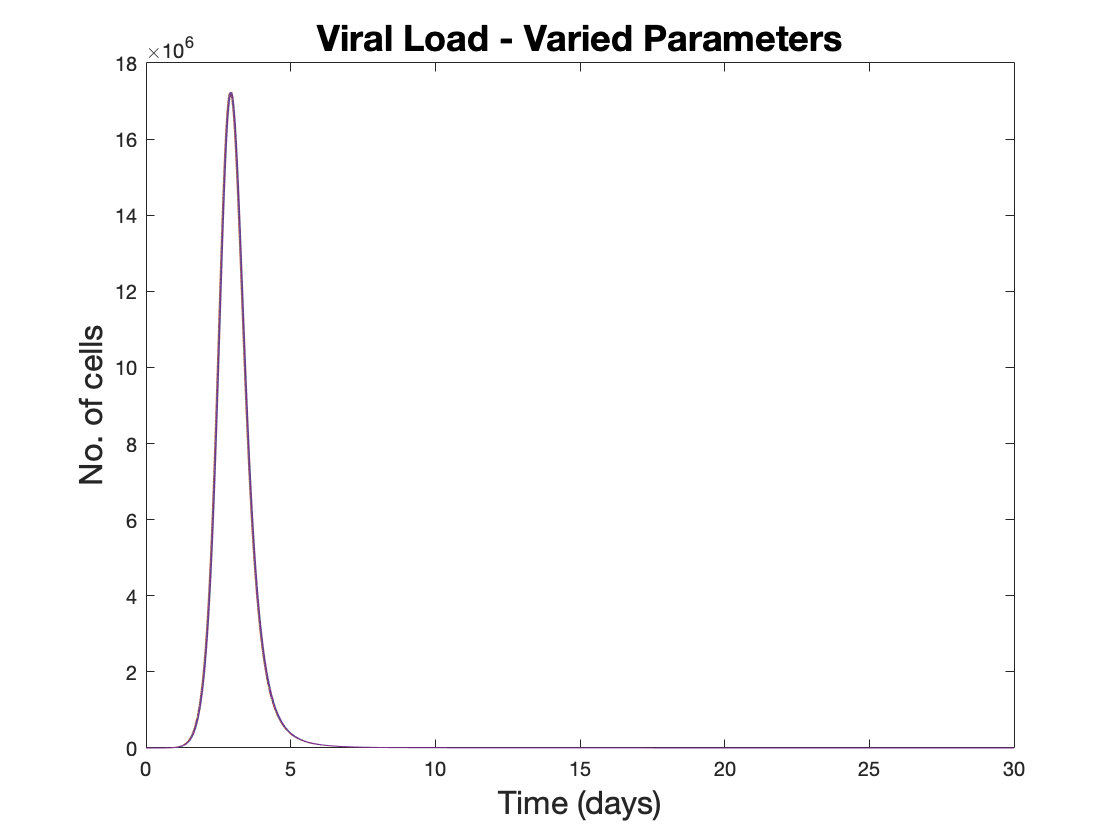



for i = 1:3000
    plot(tspan,y3(:,i));
    hold on
end
hold off
title('Viral Load - Varied Parameters','FontSize',18);
xlabel('Time (days)','FontSize',16);
ylabel('No. of cells','FontSize',16);

Dose-response model

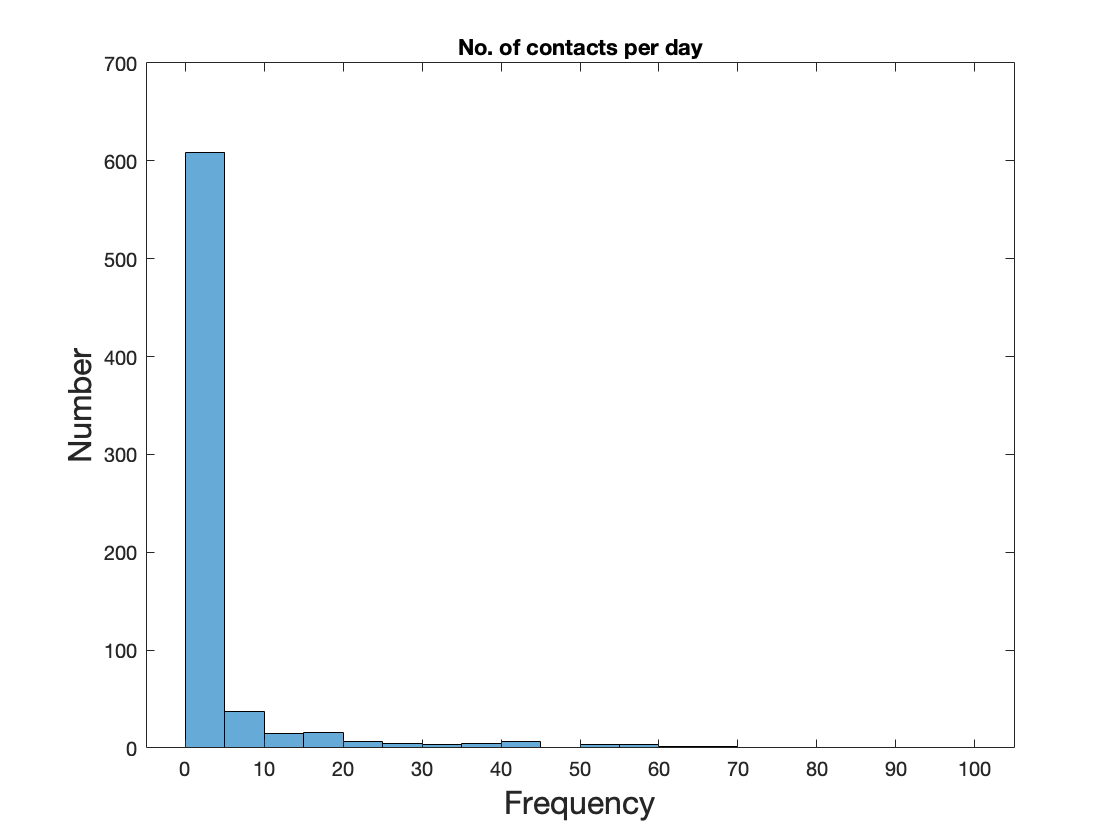

lam = 10^7; tau = 0.5; alpha = 0.8; theta = 4; rho = 40;
for i = 1:100
    Vt = y3(:,i);
    probt = (Vt.^alpha)./(lam^alpha + Vt.^alpha); 

    neta = gamrnd(theta/rho, rho, [720 1]); 
    eta = neta/24;
    %attempt to plot the gamma distribution x time
    gamplt = histogram(neta); title('No. of contacts per day');
    xlabel('Frequency','FontSize',16);
    ylabel('Number','FontSize',16);
    
    %simulating a bernoulli process
    num = rand([720 1]); 
    bern = num < probt; %1s if the condition is met, 0s otherwise
    T = bern.*probt.*eta;
    Re = sum(T);
    arre(i) = Re; %array of Re values
end


Ro1 = mean(arre);
[param, parmci] = gamfit(arre); %parameters and conf interval with gamma fit
fprintf('Gamma fit for the parameters \x03b1 and \x03b2 are %0.4f and %0.4f. \n', param)

Gamma fit for the parameters α and β are 2.3515 and 0.8466. 


fprintf('With 95%% confidence intervals of (%0.4f, %0.4f) and (%0.4f, %0.4f) respectively. \n',parmci)

With 95% confidence intervals of (2.2425, 2.4658) and (0.8030, 0.8926) respectively. 


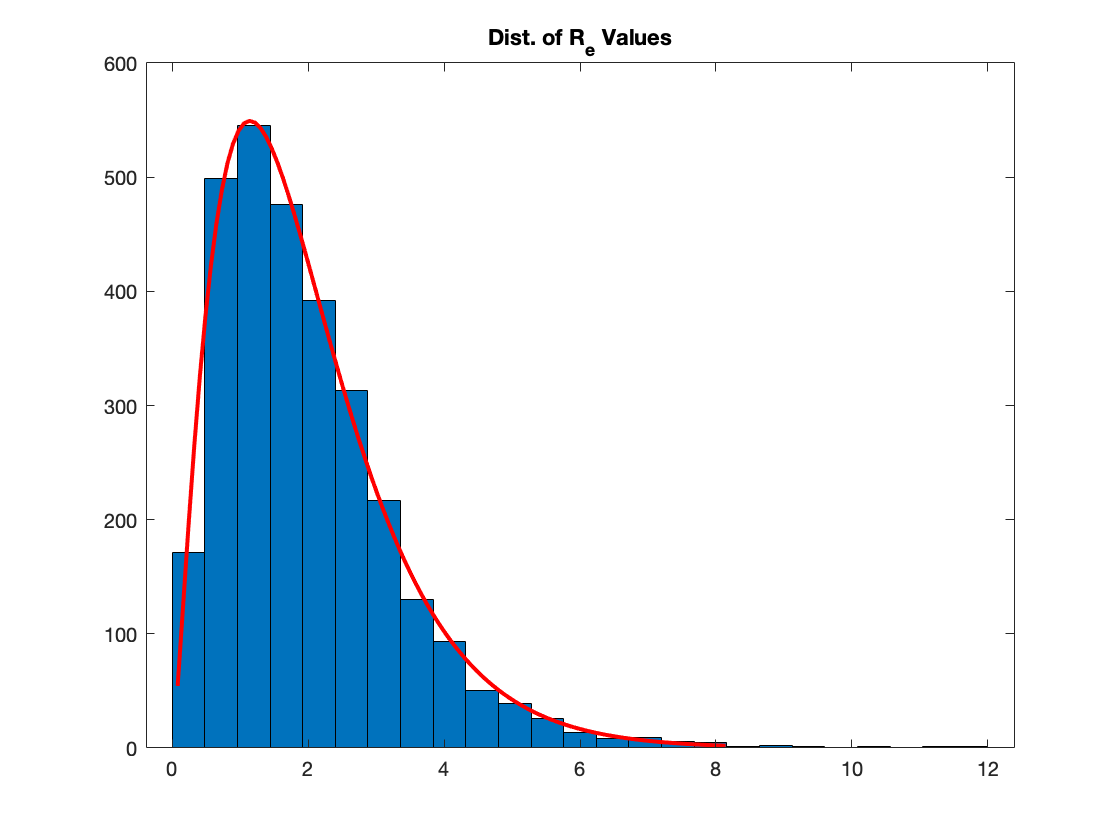

histfit(arre,25,'gamma'); %25 is the number of bins 
title('Dist. of R_e Values');

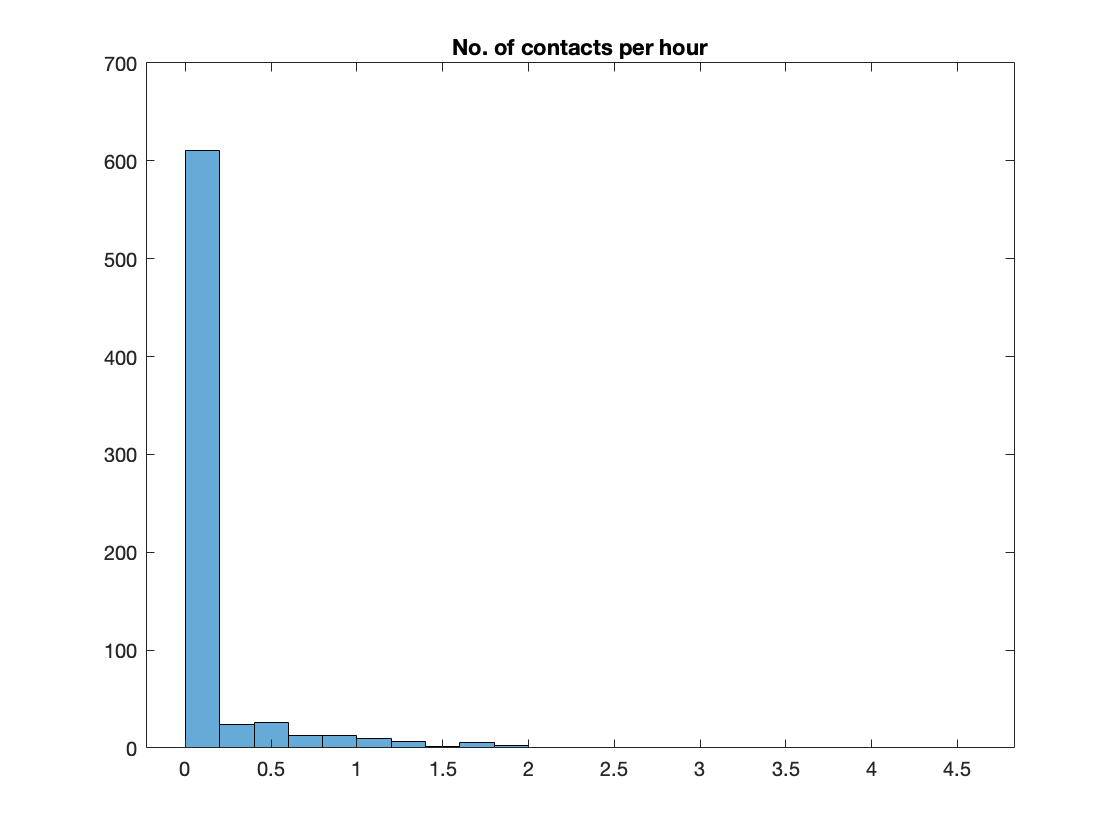

% %Alpha variant
% lam = (10^7)/nthroot(3,alpha);
% for i = 1:100
%     Vt = y3(:,i);
%     probt = (Vt.^alpha)./(lam^alpha + Vt.^alpha); 
%     eta = gamrnd(theta/rho, rho, [720 1]); 
%     eta = eta/24;
%     %attempt to plot the gamma distribution x time
%     gamplt = histogram(eta); title('No. of contacts per hour');
%     
%     %simulating a bernoulli process
%     num = rand([720 1]); 
%     bern = num < probt; %1s if the condition is met, 0s otherwise
%     T = bern.*probt.*eta;
%     Re = sum(T);
%     arre(i) = Re; %array of Re values
% end

% 
% Ro2 = mean(arre);
% [param, parmci] = gamfit(arre); %parameters and conf interval with gamma fit
% fprintf('Alpha - Gamma fit for the parameters \x03b1 and \x03b2 are %0.4f and %0.4f. \n', param)

Alpha - Gamma fit for the parameters α and β are 4.0373 and 1.1876. 


% fprintf('Alpha - With 95%% confidence intervals of (%0.4f, %0.4f) and (%0.4f, %0.4f) respectively. \n',parmci)

Alpha - With 95% confidence intervals of (3.8455, 4.2386) and (1.1277, 1.2508) respectively. 


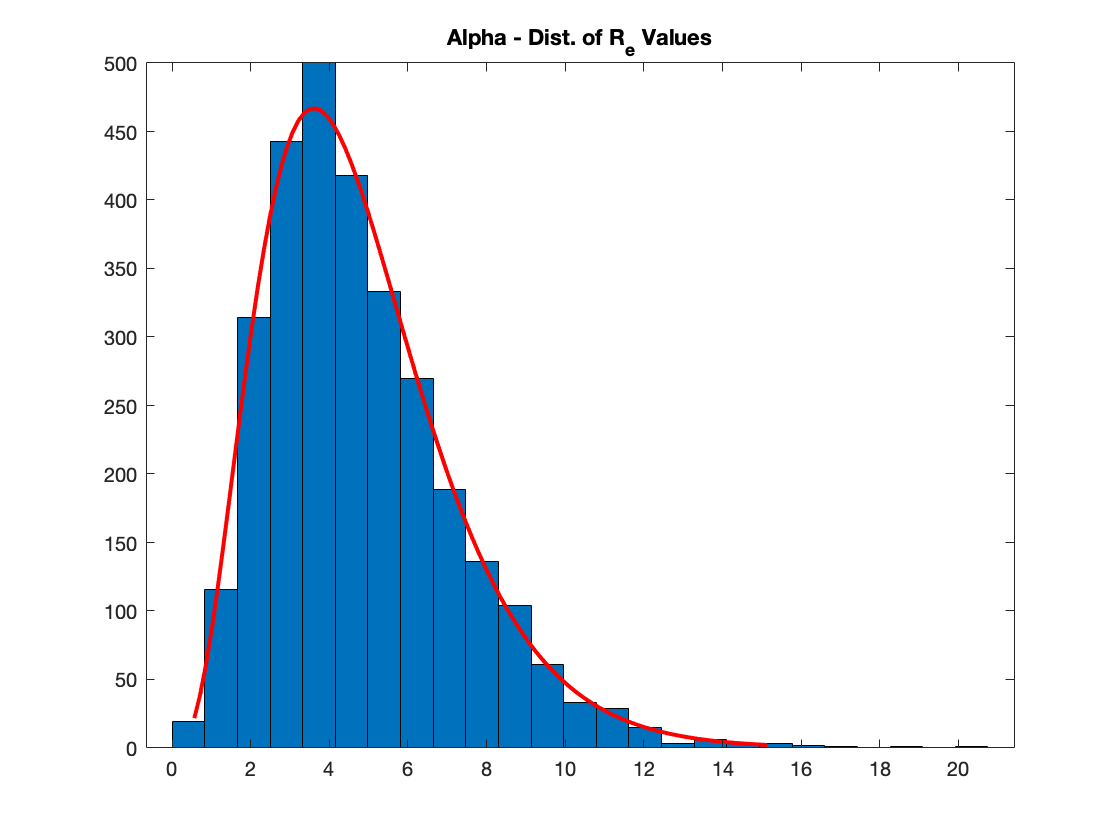

% histfit(arre,25,'gamma'); %25 is the number of bins 
% title('Alpha - Dist. of R_e Values');

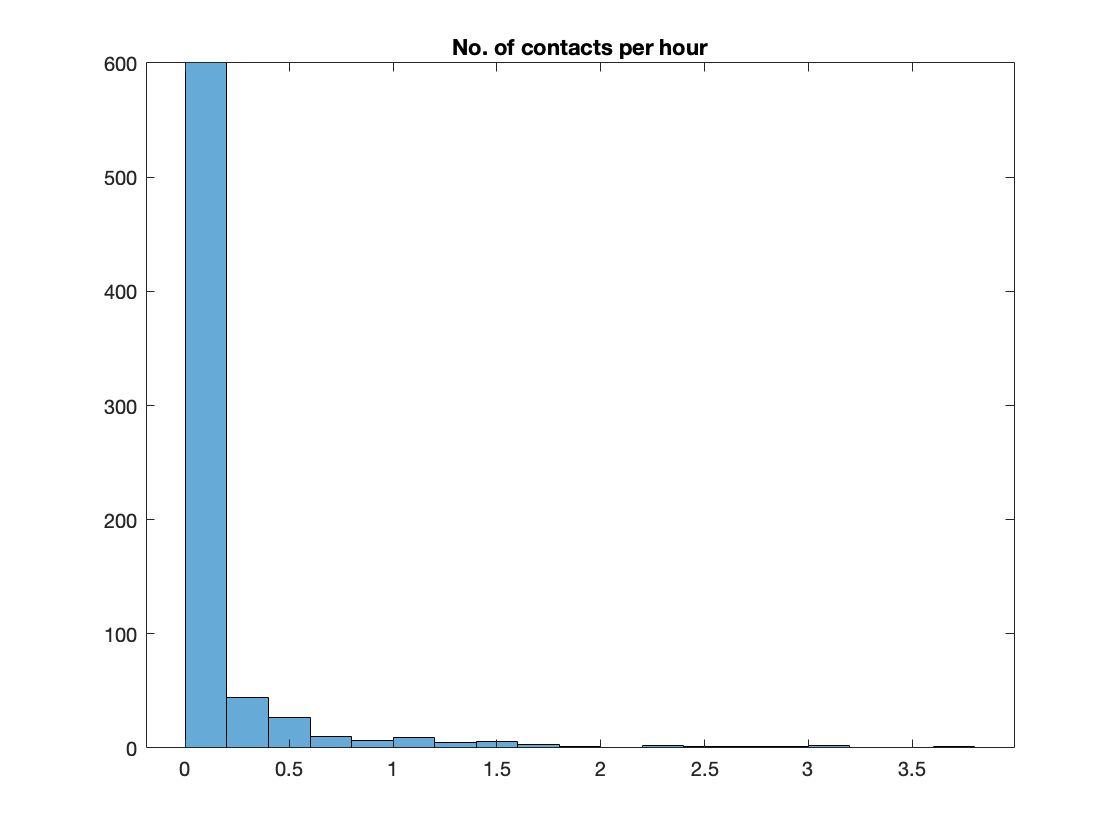

% 
% %Delta variant
% lam = (10^7)/nthroot(9,alpha);
% for i = 1:100
%     Vt = y3(:,i);
%     probt = (Vt.^alpha)./(lam^alpha + Vt.^alpha); 
%     eta = gamrnd(theta/rho, rho, [720 1]); 
%     eta = eta/24;
%     %attempt to plot the gamma distribution x time
%     gamplt = histogram(eta); title('No. of contacts per hour');
%     
%     %simulating a bernoulli process
%     num = rand([720 1]); 
%     bern = num < probt; %1s if the condition is met, 0s otherwise
%     T = bern.*probt.*eta;
%     Re = sum(T);
%     arre(i) = Re; %array of Re values
% end

% 
% Ro3 = mean(arre);
% [param, parmci] = gamfit(arre); %parameters and conf interval with gamma fit
% fprintf('Delta - Gamma fit for the parameters \x03b1 and \x03b2 are %0.4f and %0.4f. \n', param)

Delta - Gamma fit for the parameters α and β are 6.3600 and 1.3425. 


% fprintf('Delta - With 95%% confidence intervals of (%0.4f, %0.4f) and (%0.4f, %0.4f) respectively. \n',parmci)

Delta - With 95% confidence intervals of (6.0538, 6.6816) and (1.2753, 1.4132) respectively. 


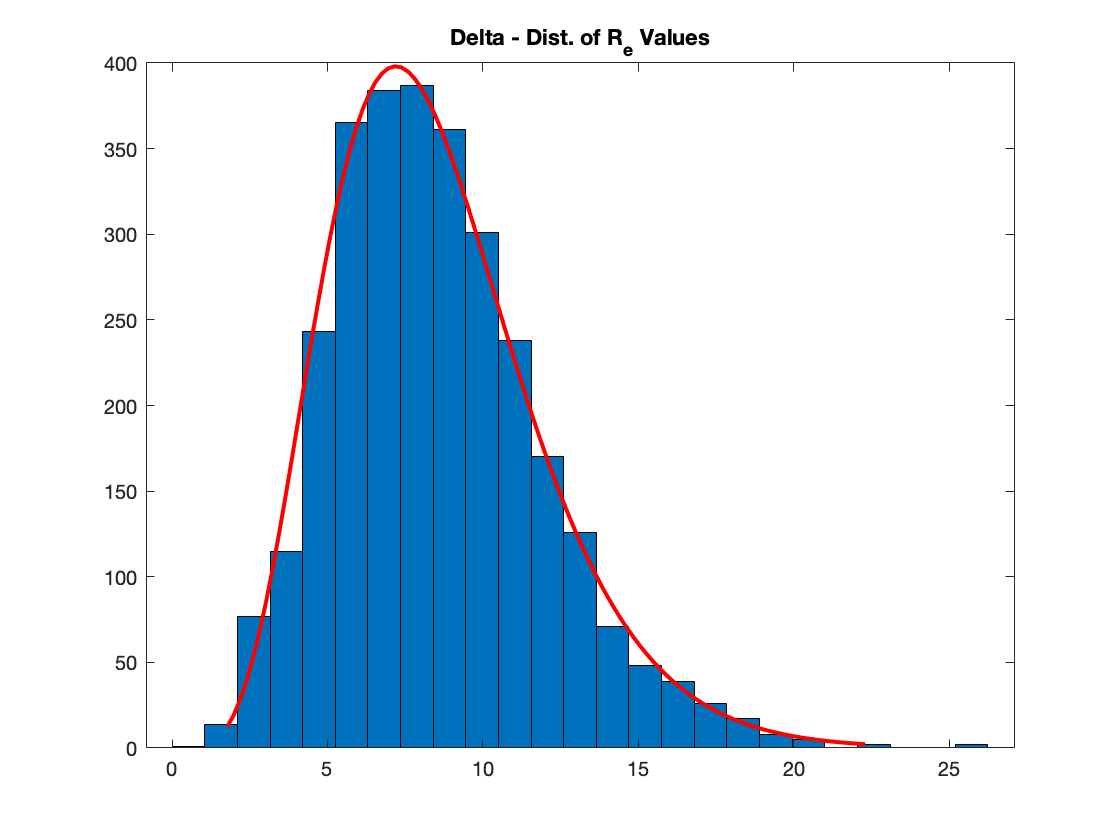

% histfit(arre,25,'gamma'); %25 is the number of bins 
% title('Delta - Dist. of R_e Values');

Masked

% lam = 10^7; tau = 0.5; alpha = 0.8; theta = 4; rho = 40;
% %new parameters
% sigma = 0.8;  %mask compliance-assumed
% Theta = 0.9; %mask adherence-assumed
% epsE = 0.8; epsT = 0.8;
% for i = 1:100
%     Vt = y3(:,i);
%     %simulating a bernoulli process - mask compliance
%     %--diff number of transmitters
%     num = rand([720 1]); 
%     bern = num < sigma; %1s if the condition is met, 0s otherwise
%    %mask adherence if compliant - bernoulli process 
%     num = rand([720 1]); 
%     bern2 = num < Theta; 
%     %wearing a mask (compliant and adherent)
% %     Bern = bern.*bern2; %still working on this
%     
%         eta = gamrnd(theta/rho, rho, [720 1]); 
%         eta = eta/24;
%         %attempt to plot the gamma distribution x time
%         gamplt = histogram(eta); title('No. of contacts per hour');
%         
%         %Masking adherence among exposed contacts - bernoulli process
%         num = rand([720 1]); 
%         kap = num < (sigma*Theta); 
%         etaMask = eta.*kap; etaUnmask = eta.*(ones(720,1)-kap);
%         
%         newVt = (1-epsE)*(1-epsT)*Vt;
%         probtMM = (newVt.^alpha)./(lam^alpha + newVt.^alpha); %MM - mask to mask
%         num = rand([720 1]); 
%         bernMM = num < probtMM; 
%         TMM = bernMM.*probtMM.*etaMask;
%         newVt = (1-epsT)*Vt;
%         probtMU = (newVt.^alpha)./(lam^alpha + newVt.^alpha); %MU - mask to unmasked
%         num = rand([720 1]); 
%         bernMU = num < probtMU; 
%         TMU = bernMU.*probtMU.*etaUnmask;
%  
% end
% 
% Ro1 = mean(arre);
% [param, parmci] = gamfit(arre); %parameters and conf interval with gamma fit
% fprintf('Gamma fit for the parameters \x03b1 and \x03b2 are %0.4f and %0.4f. \n', param)
% fprintf('With 95%% confidence intervals of (%0.4f, %0.4f) and (%0.4f, %0.4f) respectively. \n',parmci)
% histfit(arre,25,'gamma'); %25 is the number of bins 
% title('Dist. of R_e Values');




% function dy = dyfn(t,y,beta,delta,m,r,phi,parpi,gamm,omeg,q,deltaE,k)
%     fixed parameters
%     r = 10; q = 0.000024;
%     deltaE = 1; c = 15; 
%     gamm = 15; phi = 100; 
%     %rng('shuffle') %to ensure a different random number each time
%         beta=10.^normrnd(-7.23,0.2);
%         parpi=10.^normrnd(2.59,0.05); omeg=10.^normrnd(-4.55,0.01);
%         k=normrnd(0.08,0.02); m=normrnd(3.21,0.33);
%         delta=normrnd(3.13,0.02);
%     dy = [-beta*y(1)*y(3); (beta*y(1)*y(3))-(delta*(y(2)^k)*y(2))-((m*y(2)*(y(6)^r))/((y(6)^r)+(phi^r))) ...
% ; (parpi*y(2))-(gamm*y(3)); (omeg*y(2)*y(4))-(q*y(4)); q*(y(4)-y(5)); (q*y(5))-(deltaE*y(6))];
% end